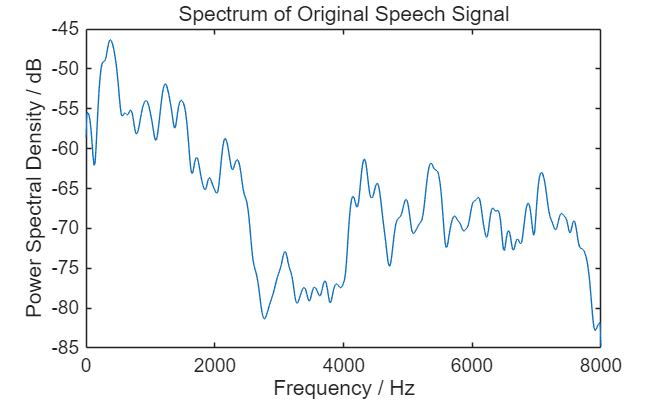

[y1,fs1]=audioread("C:\Users\18237\Desktop\2.wav");

x=y1';
window=hamming(256);
overlap=128;
NFFT=1024;
fs=16000;
[Pxx1,w]=pwelch(x,window,overlap,NFFT,fs);
figure;
plot(w,10*log10(Pxx1));
xlabel('Frequency / Hz');
ylabel('Power Spectral Density / dB');
title('Spectrum of Original Speech Signal');

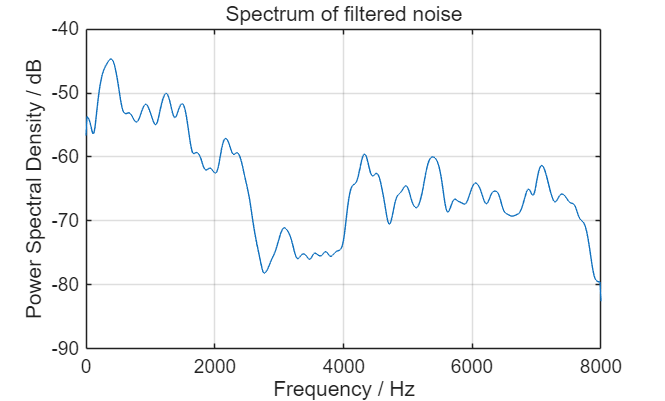

b=fir2(512,w/(fs/2),sqrt(Pxx1/max(Pxx1)));
[h,wh]=freqz(b,1,128);
noise=1-2*rand(1,length(x));
ssn=filter(b,1,noise);
[Pss, ws] = pwelch(ssn, window, overlap, NFFT, fs);
figure;
plot(ws, 10*log10(Pss));
grid on;
xlabel('Frequency / Hz');
ylabel('Power Spectral Density / dB');
title('Spectrum of filtered noise');

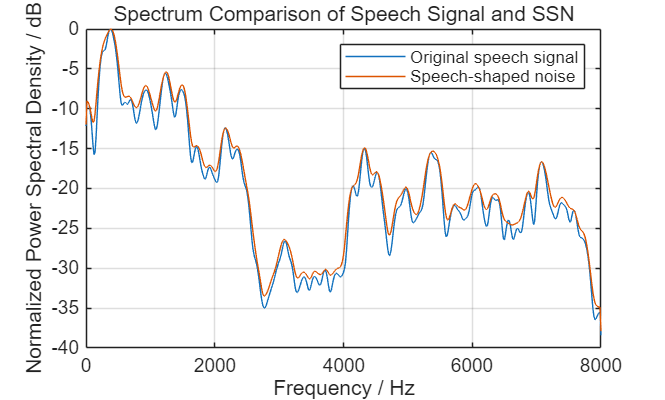

figure;
plot(w,10*log10(Pxx1/max(Pxx1)));
hold on;
plot(ws,10*log10(Pss/max(Pss)));
grid on;
xlabel('Frequency / Hz');
ylabel('Normalized Power Spectral Density / dB');
title('Spectrum Comparison of Speech Signal and SSN');
legend('Original speech signal','Speech-shaped noise');

snr=-5;
ssn=ssn/norm(ssn)*(norm(x)/(10^(snr/20)));
y0=x+ssn;
y=y0/norm(y0)*norm(x);
snr_check=20*log10(norm(x)/norm(ssn));
disp(snr_check);

   -5.0000



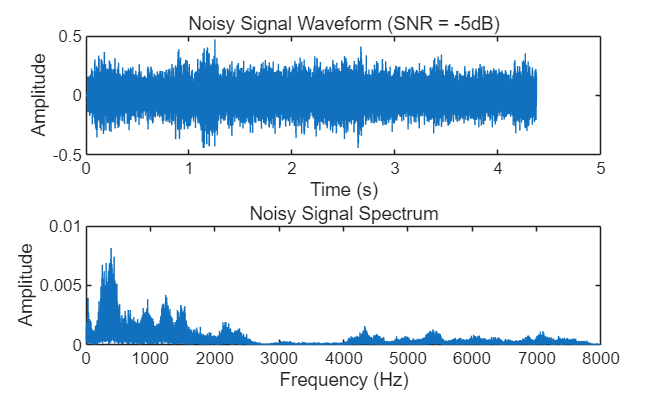

L = length(y);
t = (0:L-1) / fs; 
f = fs * (0:(L/2)) / L; 

LPF_cut_freq = 50;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2)); 


figure('Name', 'Noisy Signal (SNR=-5dB)');
subplot(2,1,1);
plot(t, y);
title('Noisy Signal Waveform (SNR = -5dB)');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y);
P1 = abs(Y_fft/L); P_single = P1(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title('Noisy Signal Spectrum');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=2

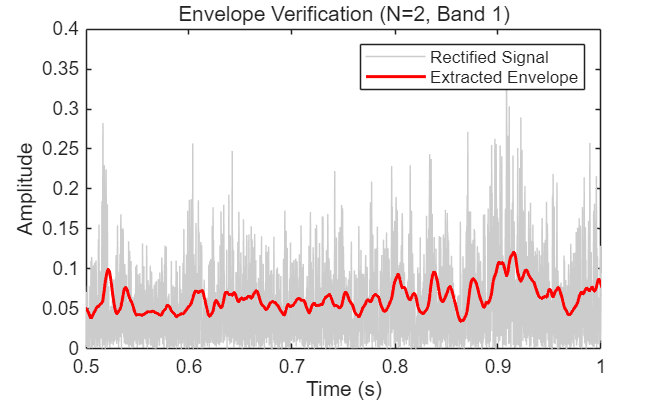

N = 2;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_2 = y_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y_2.^2));

能量验证 N=2原始信号能量: 666.6279, 归一化后信号能量: 666.6279


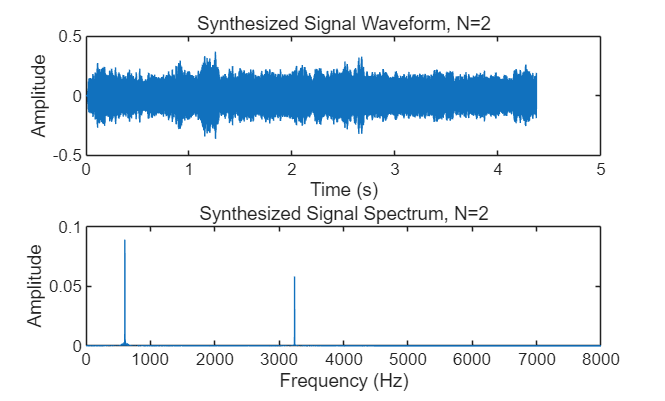


filename = sprintf('Task3_N%d.wav', N);
audiowrite(filename, y_2, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y_2);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_2);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=4

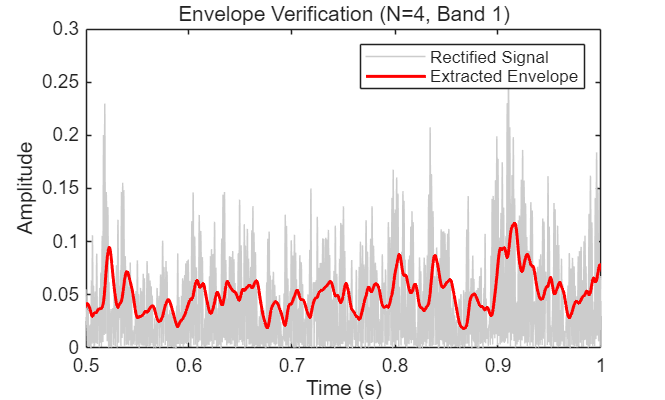

N = 4;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_4 = y_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y_4.^2));

能量验证 N=4原始信号能量: 666.6279, 归一化后信号能量: 666.6279


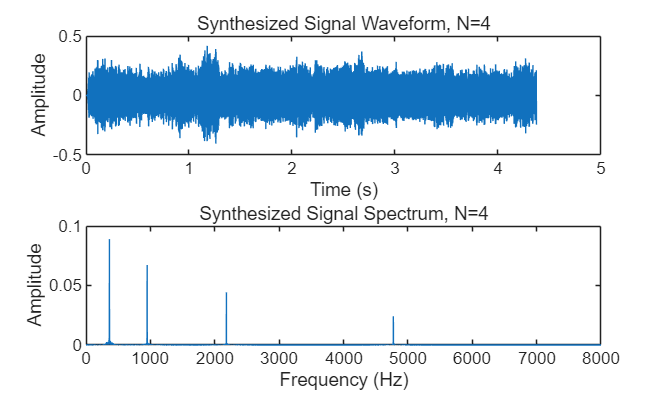


filename = sprintf('Task3_N%d.wav', N);
audiowrite(filename, y_4, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y_4);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_4);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=6

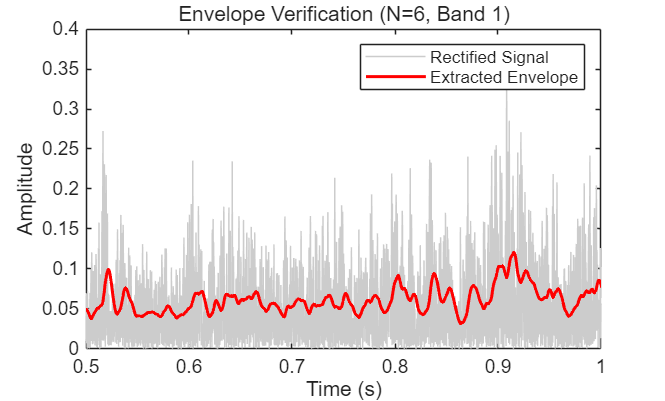

N = 6;
pass_band_lower = 200 : (7000-200)/N : 7000-(7000-200)/N;
pass_band_upper = 200+(7000-200)/N : (7000-200)/N : 7000;
center_freq = (pass_band_lower + pass_band_upper) / 2;

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_6 = y_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y_6.^2));

能量验证 N=6原始信号能量: 666.6279, 归一化后信号能量: 666.6279


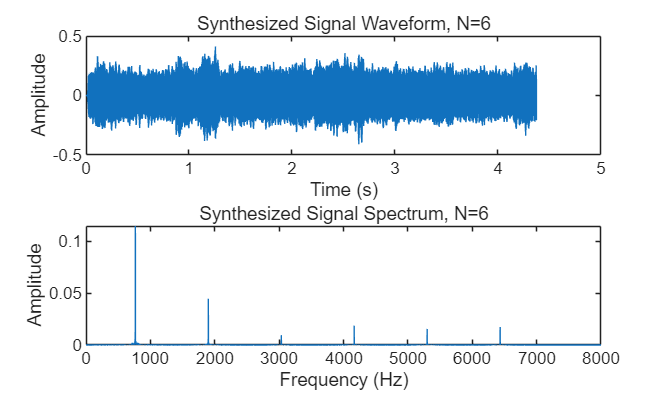


filename = sprintf('Task3_N%d.wav', N);
audiowrite(filename, y_6, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y_6);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_6);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=8

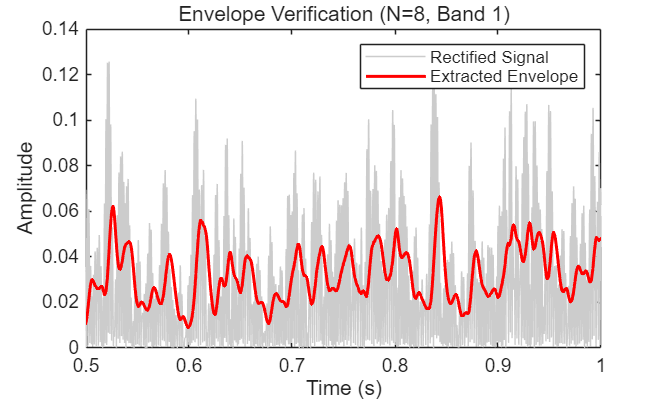


N = 8;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_8 = y_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y_8.^2));

能量验证 N=8原始信号能量: 666.6279, 归一化后信号能量: 666.6279


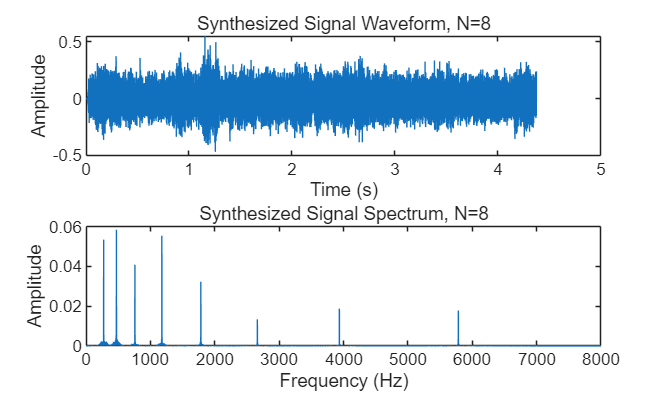


filename = sprintf('Task3_N%d.wav', N);
audiowrite(filename, y_8, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y_8);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_8);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000])

N=16

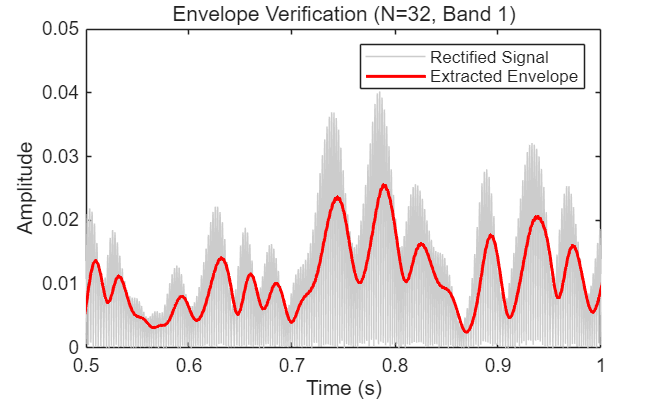

N = 32;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);

y_sum = zeros(1, length(y));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y_band = filter(B, A, y);
    y_band_abs = abs(y_band);
    y_envelope = filter(b0, a0, y_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y_modulated = y_envelope .* sine_wave;
    y_sum = y_sum + y_modulated;
end


e1 = sum(y.^2);
es = sum(y_sum.^2);
y_16 = y_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y_16.^2));

能量验证 N=32原始信号能量: 666.6279, 归一化后信号能量: 666.6279


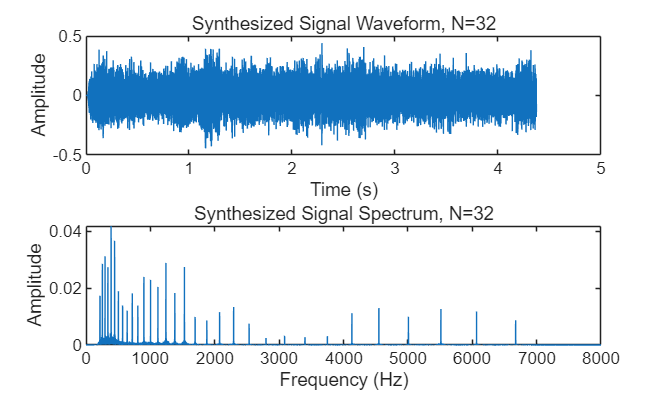


filename = sprintf('Task3_N%d.wav', N);
audiowrite(filename, y_16, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y_16);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y_16);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

%% Play Task 3 synthesized results

file_list = {
   
    'Task3_N32.wav'
};

for k = 1:length(file_list)
    [y_play, fs_play] = audioread(file_list{k});

    if size(y_play, 2) > 1
        y_play = mean(y_play, 2);
    end

    y_play = y_play / max(abs(y_play));

    fprintf('Now playing: %s\n', file_list{k});
    player = audioplayer(y_play, fs_play);
    playblocking(player);

    pause(1);
end

Now playing: Task3_N32.wav
